# Estimating Bleaching

The intensity of the synapses that are present in both tp1 and tp2 images ( unchanged, or paired synapses ) is changed due to both changes of the amount of GPF , but also bleaching. This code estimates the amount of bleaching due to one imaging session. To run this code you will need 3 csv files : coordinates of synapses in tp1, tp2 and tp3. The files are assigned to[ Dataset: 1-1GG0](https://synapse.isrd.isi.edu/chaise/record/#1/Zebrafish:Cohort/RID=1-1GG0) with the following RIDs: 

- tp1: 1-1RW0 ( 1-1EJ2_tp1.csv )

- tp2: 1-1RW2 ( 1-1EJ4_tp2.csv )

- tp3: 1-1RW4 ( 1-1EJ6_tp3.csv )

For your convenience, they are already in the *bleaching\data* folder.

## load utility functions

cd 'D:\Code\repos\synapse-redistribution\bleaching'
addpath('utils');

## Load the data

Load csv files with the extracted synapses at tp1 and tp2 and tp3. 

Provide the path to the files.

[xyz1,I1] = getCoordAndI('data\1-1EJ2_tp1.csv');

[xyz2,I2] = getCoordAndI('data\1-1EJ4_tp2.csv');

[xyz3,I3] = getCoordAndI('data\1-1EJ6_tp3.csv');

## Subtract Camera Offset

All the intensities are increased by a camera offset , set to ~102 counts, to facilitate imaging. To get a better estimate of the flourescence due to labeling, we subtract the camera offset from the raw intensity values.

cam_offset = 102;

I1 = I1 - cam_offset;
I2 = I2 - cam_offset;
I3 = I3 - cam_offset;
disp('Camera offset subtracted!')

Camera offset subtracted!


## Register tp2 to tp1 and tp3 to tp2

The synapses we've loaded are not in order - we need to pair them. The code belows pairs the points in a couple of iterations. Plots demonstrate the pairing at each iteration. A unique pair means that a point in tp1 is the nearest neighbour for only one point in tp2 (same fot tp2 and tp3).

## tp2 TO tp1 : 

disp('____tp2 TO tp1____');

____tp2 TO tp1____


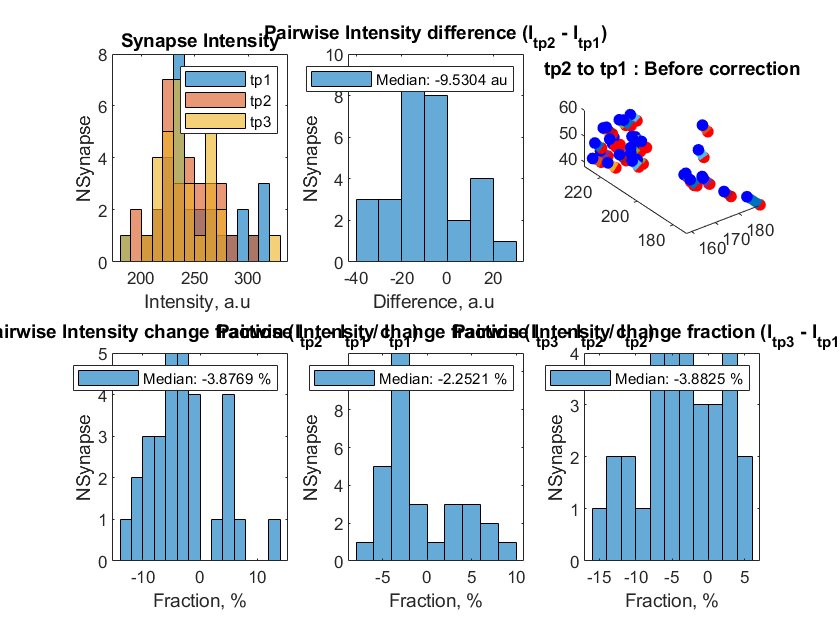

from_xyz = xyz2;
to_xyz = xyz1;

[idx,~] = knnsearch(to_xyz,from_xyz);

plotTimePoints(to_xyz,from_xyz,idx)
title('tp2 to tp1 : Before correction');


disp(['tp2 to tp1 total points :',num2str(length(to_xyz))]);

tp2 to tp1 total points :30


disp('Before correction');

Before correction


disp(['uniquely paired :',num2str(length((unique(idx))))])

uniquely paired :23


Register based on the most common distance (mode)

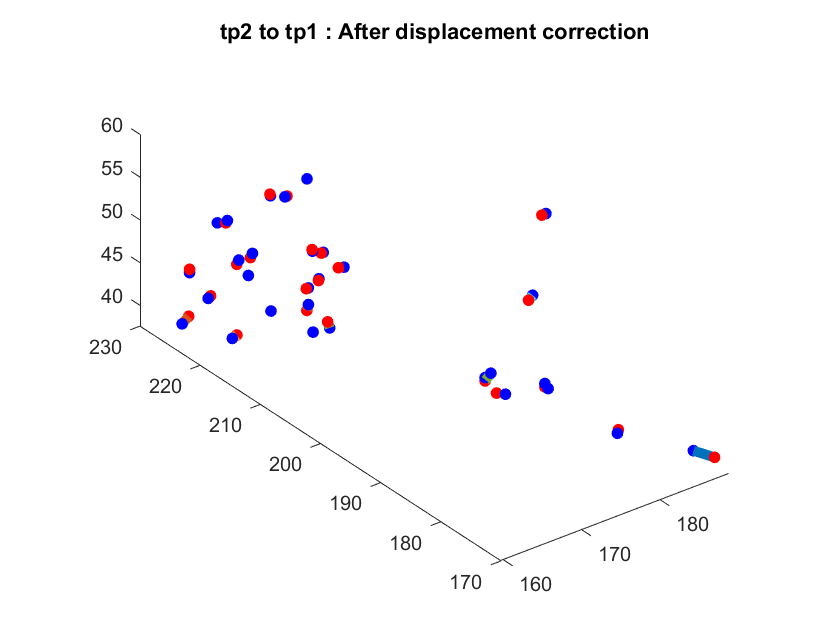

from_xyz_corrected = correctDisplacement(from_xyz,to_xyz,idx); 
[idx,~] = knnsearch(to_xyz,from_xyz_corrected); %,'K',1);
 
% plot it
f1 = figure;
plotTimePoints(to_xyz,from_xyz_corrected,idx)
title('tp2 to tp1 : After displacement correction');

disp('After displacement correction');

After displacement correction


disp(['uniquely paired :',num2str(length((unique(idx))))]);

uniquely paired :29


correction and repairing

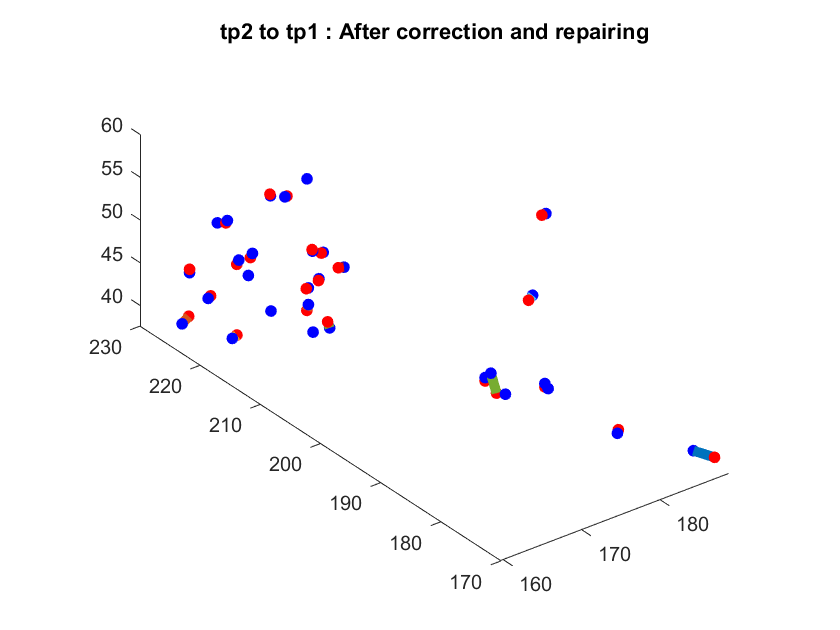

[idx,unp_from_idx,unp_to_idx] = uniqueNN(from_xyz_corrected, to_xyz); % From , TO 
idx(unp_from_idx) = unp_to_idx;

f2 = figure;
plotTimePoints(to_xyz,from_xyz_corrected,idx)
title('tp2 to tp1 : After correction and repairing');

disp('After correction and repairing');

After correction and repairing


disp(['uniquely paired :',num2str(length((unique(idx))))]) 

uniquely paired :30



I1to2 = I1(idx);

## tp3 TO tp2 : 

disp('____tp3 TO tp2____');

____tp3 TO tp2____


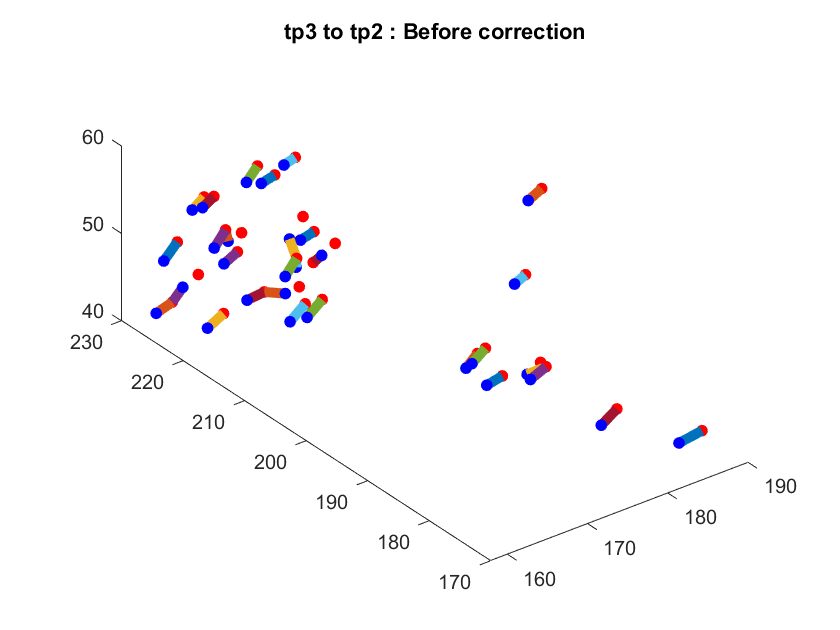

from_xyz = xyz2;
to_xyz = xyz3;

[idx,~] = knnsearch(to_xyz,from_xyz); %,'K',1); % To , From 
f3 = figure;
plotTimePoints(to_xyz,from_xyz,idx)
title('tp3 to tp2 : Before correction');


disp(['tp3 to tp2 total points :',num2str(length(to_xyz))]);

tp3 to tp2 total points :30


disp('Before correction');

Before correction


disp(['uniquely paired :',num2str(length((unique(idx))))])

uniquely paired :24


Register based on the most common distance (mode)

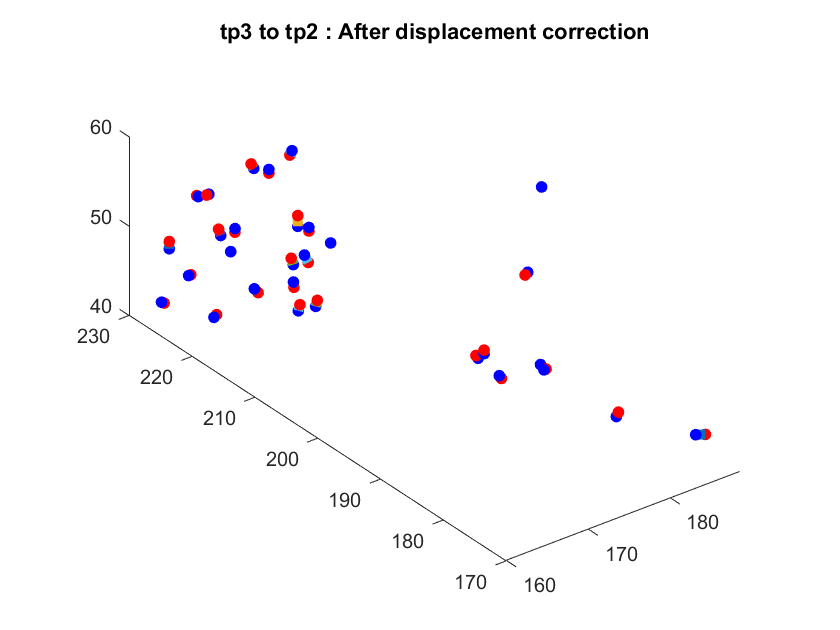

from_xyz_corrected = correctDisplacement(from_xyz,to_xyz,idx); 
[idx,~] = knnsearch(to_xyz,from_xyz_corrected); %,'K',1);
 
% plot it
f4 = figure;
plotTimePoints(to_xyz,from_xyz_corrected,idx)
title('tp3 to tp2 : After displacement correction');

disp('After displacement correction');

After displacement correction


disp(['uniquely paired :',num2str(length((unique(idx))))])  

uniquely paired :30



I3to2 = I3(idx);

## Look at overall intensity

this plots different intensity statistics. 

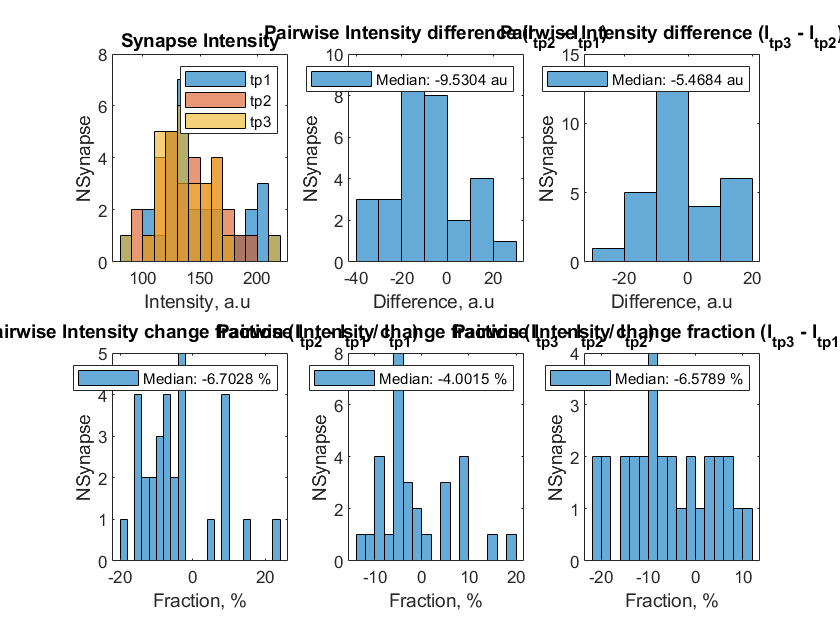

f5 = figure;
subplot(2,3,1);
histogram(I1, 'BinWidth',10)
hold on
histogram(I2, 'BinWidth',10)
hold on
histogram(I3, 'BinWidth',10)
legend('tp1','tp2','tp3');
title('Synapse Intensity');
xlabel('Intensity, a.u ');
ylabel('NSynapse');

% tp1 and tp2
subplot(2,3,4);
histogram(((I2-I1to2)./I1to2)*100, 'BinWidth',2)
legend(['Median: ',num2str(median(((I2-I1to2)./I1to2)*100)),' %']);
title('Pairwise Intensity change fraction (I_{tp2} - I_{tp1} / I_{tp1})' );
xlabel('Fraction, %');
ylabel('NSynapse');
%ylim([0 6]);

% tp2 and tp3
subplot(2,3,5);
histogram(((I3to2-I2)./I2)*100, 'BinWidth',2)
legend(['Median: ',num2str(median(((I3to2-I2)./I2)*100)),' %']);
title('Pairwise Intensity change fraction (I_{tp3} - I_{tp2} / I_{tp2})' );
xlabel('Fraction, %');
ylabel('NSynapse');
%ylim([0 6]);

% tp2 and tp3
subplot(2,3,6);
histogram(((I3to2-I1to2)./I1to2)*100, 'BinWidth',2)
legend(['Median: ',num2str(median(((I3to2-I1to2)./I1to2)*100)),' %']);
title('Pairwise Intensity change fraction (I_{tp3} - I_{tp1} / I_{tp1})' );
xlabel('Fraction, %');
ylabel('NSynapse');
%ylim([0 6]);

% tp1 and tp2
subplot(2,3,2);
histogram((I2-I1to2), 'BinWidth',10)
legend(['Median: ',num2str(median(I2-I1to2)),' au']);
title('Pairwise Intensity difference (I_{tp2} - I_{tp1})' );
xlabel('Difference, a.u ');
ylabel('NSynapse');
%ylim([0 6]);

% tp2 and tp3
subplot(2,3,3);
histogram((I3to2-I2), 'BinWidth',10)
legend(['Median: ',num2str(median(I3to2-I2)),' au']);
title('Pairwise Intensity difference (I_{tp3} - I_{tp2})' );
xlabel('Difference, a.u');
ylabel('NSynapse');

%ylim([0 6]);

## Write out csv

Save intensity info of each point in a csv. Provede the path where to save.

savePath = 'data\';
fileName = 'paired_Intensity_data_minus_camera_offset.xlsx';

write the csv

alphabet = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ';
iLetter = 0;
dataLength = length(I1);

iLetter = iLetter + 1;
writeColumn([savePath,fileName],alphabet(iLetter),1,1,{'tp1'}); 
writeColumn([savePath,fileName],alphabet(iLetter),2,dataLength+1,I1to2);  
iLetter = iLetter + 1;
writeColumn([savePath,fileName],alphabet(iLetter),1,1,{'tp2'}); 
writeColumn([savePath,fileName],alphabet(iLetter),2,dataLength+1,I2); 
iLetter = iLetter + 1;
writeColumn([savePath,fileName],alphabet(iLetter),1,1,{'tp3'}); 
writeColumn([savePath,fileName],alphabet(iLetter),2,dataLength+1,I3to2); 
iLetter = iLetter + 1;
writeColumn([savePath,fileName],alphabet(iLetter),1,1,{'(tp2 - tp1)/tp1'}); 
ratio = (I2 - I1to2)./I1to2;
writeColumn([savePath,fileName],alphabet(iLetter),2,dataLength+1,ratio); 
iLetter = iLetter + 1;
writeColumn([savePath,fileName],alphabet(iLetter),1,1,{'(tp3 - tp2)/tp2'}); 
ratio = (I3to2 - I2)./I2;
writeColumn([savePath,fileName],alphabet(iLetter),2,dataLength+1,ratio); 
iLetter = iLetter + 1;
writeColumn([savePath,fileName],alphabet(iLetter),1,1,{'(tp3 - tp1)/tp1'});
ratio = (I3to2 - I1to2)./I1to2;
writeColumn([savePath,fileName],alphabet(iLetter),2,dataLength+1,ratio); 
disp('Done');

Done


## Helper functions

Keeping the plotting function here in case you want to change how the plots look like. 

function plotTimePoints(xyz1,xyz2,idx)
% plots paired points from xyz1,xyz2 using idx for pairing
    for iSynn = 1:length(xyz1)
        plot3([xyz2(iSynn,1),xyz1(idx(iSynn),1)],[xyz2(iSynn,2),xyz1(idx(iSynn),2)],[xyz2(iSynn,3),xyz1(idx(iSynn),3)],'LineWidth',5);
        hold on
    end
    plot3(xyz1(:,1),xyz1(:,2),xyz1(:,3),'.','Color',[1 0 0],'MarkerSize',20);
    hold on
    plot3(xyz2(:,1),xyz2(:,2),xyz2(:,3),'.','Color',[0 0 1],'MarkerSize',20);
    daspect([1 1 1])
end